# Algoritmo Genetico para el Problema del Vendedor Viajero (TSP)

La esturctura del cromosoma, seleccion, cruce y mutacion estan definidos en Cromosoma.mlx

El problema geometrico esta definido en tsp.mlx.

## Parametros

clear all; close all; clc;
rng('shuffle');

N = 26; % numero de ciudades
n_poblacion = 1000; % tamano de poblacion
max_generaciones = 500; % tope de generaciones (criterio de parada)
stall_generaciones = 100; % generaciones sin mejora -> stall condition
prob_mutacion  = 0.99; % probabilidad de mutar cada hijo generado


## Generacion del problema

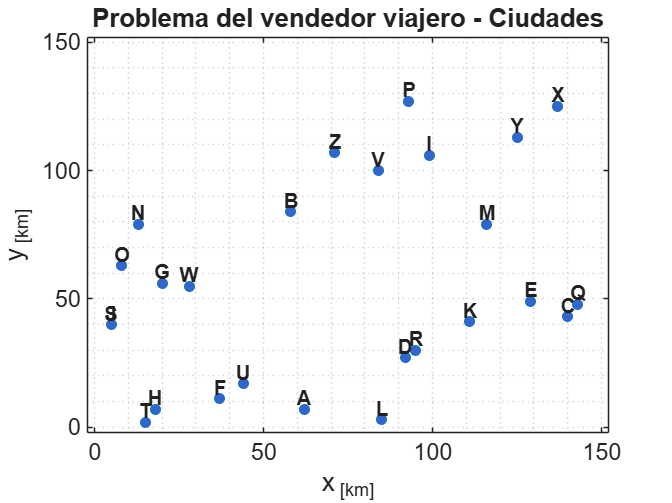

coordenadas = round(rand(N,2) .* 150);
figure('Name','Problema del vendedor viajero');
eje = subplot(1,1,1);
plot(coordenadas(:,1), coordenadas(:,2), 'o', 'MarkerSize',6, ...
    'MarkerFaceColor',[0.2 0.4 0.8]);
hold on;
xlabel('x_{ [km]}');
ylabel('y_{ [km]}');
set(eje,'FontSize',14);
axis([-2 152 -2 152]);
title('Problema del vendedor viajero - Ciudades');
grid minor;
for k = 1:N
    texto = text(coordenadas(k,1), coordenadas(k,2), sprintf('%c','A'+k-1));
    set(texto,'FontSize',12,'HorizontalAlignment','center', ...
        'FontWeight','bold','VerticalAlignment','bottom');
end

## Algoritmo genetico

%Build Initial Population
poblacion = PoblacionInicial(n_poblacion, N);

%Costo inicial
costos = Fitness(poblacion, coordenadas);

%Best 
[BestCost, pos_Best] = min(costos);
Best = poblacion(pos_Best, :); %Mejor solución inicial

historial = zeros(max_generaciones, 1);  %Historial menor costo por generacion
historialMedia = zeros(max_generaciones, 1);  %Historial del costo promedio de la poblacion por generacion
generacionesSinMejora = 0; %Stall condition

gen = 0;
while gen < max_generaciones && generacionesSinMejora < stall_generaciones
    gen = gen + 1;

    % Seleccion de padres
    Padres = seleccionPadres(n_poblacion);

    % Proxima generación
    hijos = Breed(poblacion, Padres, prob_mutacion);
    poblacionCombinada = [poblacion; hijos];
    costosCombinados = Fitness(poblacionCombinada, coordenadas);

    % Elitismo = Tamaño de la población constante, solo se conservan los mejores
    [costosOrdenados, orden] = sort(costosCombinados, 'ascend');
    poblacion = poblacionCombinada(orden(1:n_poblacion), :); %Se eliminan los peores
    costos = costosOrdenados(1:n_poblacion);

    mejorGeneracion = costos(1);

    %Actualización del historial
    if mejorGeneracion < BestCost - 1e-9 %Se mira si el cambio es suficiente o no
        BestCost = mejorGeneracion;
        Best = poblacion(1, :);
        generacionesSinMejora = 0;
    else
        generacionesSinMejora = generacionesSinMejora + 1;
    end

    historial(gen) = BestCost;
    historialMedia(gen) = mean(costos);   %Promedio de toda la poblacion
    fprintf('Generacion %3d | Mejor costo: %8.3f km | Media: %8.3f km | Sin mejora: %3d/%d\n', ...
        gen, BestCost, historialMedia(gen), generacionesSinMejora, stall_generaciones);
end

Generacion   1 | Mejor costo: 1428.402 km | Media: 2020.178 km | Sin mejora:   1/100
Generacion   2 | Mejor costo: 1428.402 km | Media: 1989.696 km | Sin mejora:   2/100
Generacion   3 | Mejor costo: 1428.402 km | Media: 1921.008 km | Sin mejora:   3/100
Generacion   4 | Mejor costo: 1361.467 km | Media: 1848.042 km | Sin mejora:   0/100
Generacion   5 | Mejor costo: 1361.467 km | Media: 1782.843 km | Sin mejora:   1/100
Generacion   6 | Mejor costo: 1361.467 km | Media: 1774.868 km | Sin mejora:   2/100
Generacion   7 | Mejor costo: 1361.467 km | Media: 1761.769 km | Sin mejora:   3/100
Generacion   8 | Mejor costo: 1322.170 km | Media: 1753.905 km | Sin mejora:   0/100
Generacion   9 | Mejor costo: 1322.170 km | Media: 1719.570 km | Sin mejora:   1/100
Generacion  10 | Mejor costo: 1322.170 km | Media: 1676.842 km | Sin mejora:   2/100
Generacion  11 | Mejor costo: 1322.170 km | Media: 1643.286 km | Sin mejora:   3/100
Generacion  12 | Mejor costo: 1261.097 km | Media: 1620.559 km | 


historial = historial(1:gen);
historialMedia = historialMedia(1:gen);

if generacionesSinMejora >= stall_generaciones
    fprintf('\nDetenido por STALL CONDITION en la generacion %d.\n', gen);
else
    fprintf('\nDetenido por alcanzar el maximo de generaciones (%d).\n', max_generaciones);
end


Detenido por STALL CONDITION en la generacion 255.


fprintf('Mejor ruta encontrada: '); disp(Best);

Mejor ruta encontrada:     17     3     5    11    18     4    12     1    21     6     8    20    10    19    23     7    15    14     2    26    22     9    16    24    25    13



fprintf('Costo (distancia total): %.3f km\n', BestCost);

Costo (distancia total): 532.346 km


## Resultados

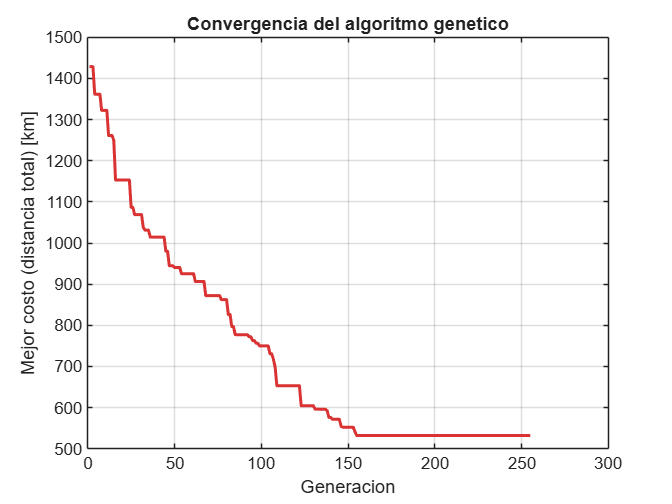

figure('Name','Convergencia del algoritmo genetico');
plot(1:gen, historial, 'LineWidth', 1.8, 'Color',[0.85 0.2 0.2]);
xlabel('Generacion');
ylabel('Mejor costo (distancia total) [km]');
title('Convergencia del algoritmo genetico');
grid on;

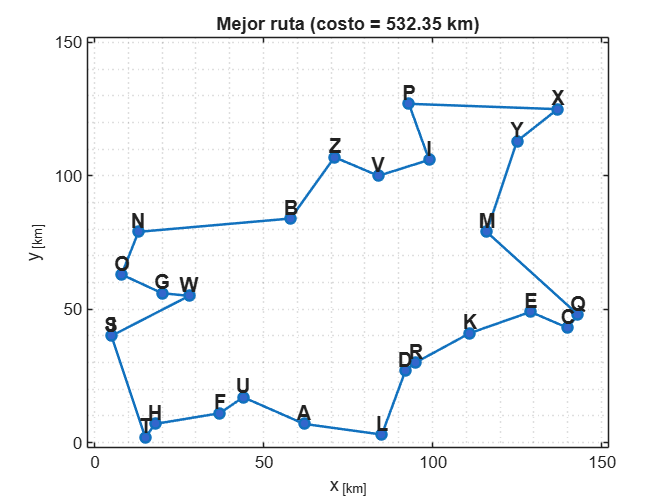


figure('Name','Mejor ruta encontrada');
rutaCoords = coordenadas(Best, :); %Ruta de la mejor soluci
rutaCoords = [rutaCoords; rutaCoords(1,:)]; %Cerrar el ciclo
plot(rutaCoords(:,1), rutaCoords(:,2), '-o', 'LineWidth', 1.5, ...
    'MarkerFaceColor',[0.2 0.4 0.8]);
hold on;
for k = 1:N
    texto = text(coordenadas(k,1), coordenadas(k,2), sprintf('%c','A'+k-1));
    set(texto,'FontSize',12,'HorizontalAlignment','center', ...
        'FontWeight','bold','VerticalAlignment','bottom');
end
xlabel('x_{ [km]}');
ylabel('y_{ [km]}');
axis([-2 152 -2 152]);
title(sprintf('Mejor ruta (costo = %.2f km)', BestCost));
grid minor;

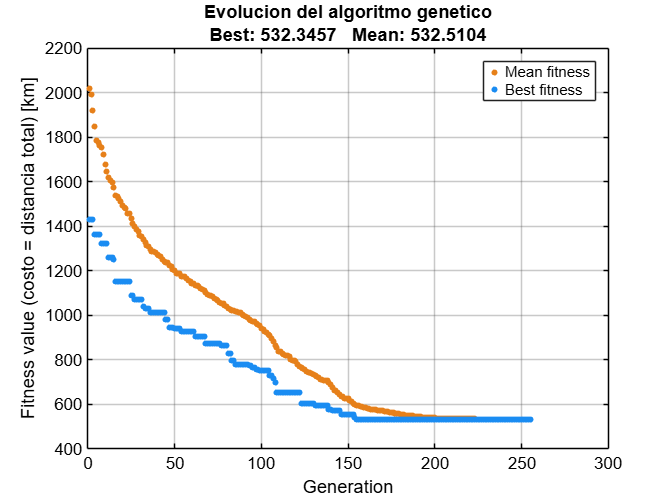


figuraConv = figure('Name','Evolución del algoritmo genetico', ...
    'Color',[1 1 1]);   % fondo de la VENTANA en blanco
ejeConv = axes('Parent', figuraConv);
hold(ejeConv, 'on');

% Mean fitness: refleja el movimiento/dispersion de TODA la poblacion
plot(ejeConv, 1:gen, historialMedia, 'o', ...
    'MarkerSize',3, 'MarkerFaceColor',[0.90 0.50 0.10], ...
    'MarkerEdgeColor',[0.90 0.50 0.10], 'DisplayName','Mean fitness');

% Best fitness: el mejor individuo de cada generacion
plot(ejeConv, 1:gen, historial, 'o', ...
    'MarkerSize', 3, 'MarkerFaceColor',[0.10 0.55 0.95], ...
    'MarkerEdgeColor',[0.10 0.55 0.95], 'DisplayName','Best fitness');

set(ejeConv, 'Color',[1 1 1], 'XColor',[0 0 0], 'YColor',[0 0 0], ...
    'GridColor',[0.3 0.3 0.3], 'GridAlpha', 0.3);
xlabel(ejeConv, 'Generation', 'Color',[0 0 0]);
ylabel(ejeConv, 'Fitness value (costo = distancia total) [km]', 'Color',[0 0 0]);
title(ejeConv, {'Evolucion del algoritmo genetico', ...
    sprintf('Best: %.4f   Mean: %.4f', historial(end), historialMedia(end))}, ...
    'Color',[0 0 0]);
legend(ejeConv, 'Location','northeast', 'TextColor',[0 0 0], 'Color',[1 1 1]);
grid(ejeConv, 'on');
box(ejeConv, 'on');

## Funciones

function poblacion = PoblacionInicial(n_poblacion, N)
% Cada individuo es una permutacion de las N ciudades.
    poblacion = zeros(n_poblacion, N);
    for i = 1:n_poblacion
        poblacion(i, :) = randperm(N);
    end
end

function Seleccionados = seleccionPadres(n_poblacion)
% Selecciona aleatoriamente un numero par de individuos parejas
    vectorSeleccion = zeros(n_poblacion, 1);
    maxParejas = floor(n_poblacion / 2); % Maximo numero de parejas posibles
    numParejas = randi([1, maxParejas]);  %Numero real de parejas
    numSeleccionados = numParejas * 2; %Se seleccionan 2 cromosomas para la pareja

    posiciones = randperm(n_poblacion, numSeleccionados); %Sorteo de los padres
    vectorSeleccion(posiciones) = 1;
    Seleccionados = find(vectorSeleccion == 1); %Indices de los padres seleccionados
end


function hijo = cruce(padre1, padre2)
    %Se toma un bloque del padre 1 y se copia al hijo en la misma posición
    %El resto de posiciones se toma del padre 2 en el orden que salgan
    %No se pueden tener repetidos, de forma que los hijos son validos

    N = length(padre1); 
    tamMaxBloque = max(1, floor(2*N / 3)); %Maximo tañano del bloque
    tamBloque = randi([1, tamMaxBloque]); %Tamaño real del bloque 

    %Se asegura que el bloque quepa completo
    inicio = randi([1, N - tamBloque + 1]); %Posición donde inicia el bloque
    fin = inicio + tamBloque - 1; %Posición donde termina el bloque
    
    %Pegar el bloque en el hijo
    bloque = padre1(inicio:fin);
    hijo = zeros(1, N);
    hijo(inicio:fin) = bloque;

    restantes = padre2(~ismember(padre2, bloque)); %Se seleccionan los faltantes del padre 2
    posicionesLibres = [1:(inicio - 1), (fin + 1):N];
    hijo(posicionesLibres) = restantes;
end


function individuoMutadoG = Big_mutacion(individuo)
% Mutacion por intercambio entre dos posiciones aleatorias.
    N = length(individuo);
    individuoMutadoG = individuo;
    pos_i = randi(N); %Posicion 1
    pos_f = randi(N); %Posicion 2

    %Intercambio
    if pos_i ~= pos_f
        temp = individuoMutadoG(pos_i);
        individuoMutadoG(pos_i) = individuoMutadoG(pos_f);
        individuoMutadoG(pos_f) = temp;
    end
end


function individuoMutadoP = Small_mutacion(individuo)
% Mutacion por intercambio con un vecino.
    N = length(individuo);
    individuoMutadoP = individuo;
    pos = randi(N);

    %Limites
    if pos == 1
        vecino = 2;
    elseif pos == N
        vecino = N - 1;
    else
        %Se decide si es coge el de la izquierda o el de la derecha
        if rand() < 0.5
            vecino = pos - 1;
        else
            vecino = pos + 1;
        end
    end

    %Intercambio
    temp = individuoMutadoP(pos);
    individuoMutadoP(pos) = individuoMutadoP(vecino);
    individuoMutadoP(vecino) = temp;
end


function hijos = Breed(poblacion, Padres, prob_mutacion)
%Cada cruce produce 2 hijos invirtiendo el orden de los padres
    numPadres = numel(Padres);
    numParejas = floor(numPadres / 2); %Asegurarse de que sean parejas
    N = size(poblacion, 2); %Tamaño de los cromosomas
    hijos = zeros(2 * numParejas, N);

    for k = 1:numParejas 
        p1 = poblacion(Padres(2*k - 1), :); %Primer padre
        p2 = poblacion(Padres(2*k), :); %Segundo padre

        h1 = cruce(p1, p2);
        h2 = cruce(p2, p1);

        %Se decide si muta y que tip de mutacióm
        if rand() < prob_mutacion
            if rand() < 0.5
                h1 = Small_mutacion(h1);
            else
                h1 = Big_mutacion(h1);
            end
        end
        if rand() < prob_mutacion
            if rand() < 0.5
                h2 = Small_mutacion(h2);
            else
                h2 = Big_mutacion(h2);
            end
        end

        hijos(2*k - 1, :) = h1;
        hijos(2*k, :)     = h2;
    end
end


function costo = costoRuta(individuo, coordenadas)
    ruta = coordenadas(individuo, :); %Ruta del cromosoma
    ruta = [ruta; ruta(1, :)]; %Camino cerrado
    diferencias = diff(ruta, 1, 1); %Diferencias entre filas
    distancias = sqrt(sum(diferencias.^2, 2)); %Distancias entre ciudades
    costo = sum(distancias); %Distancia total
end
    
function costos = Fitness(poblacion, coordenadas)
%Evalua la funión de costo para cada individuo de la poblacion.
    n_poblacion = size(poblacion, 1);
    costos = zeros(n_poblacion, 1);
    for i = 1:n_poblacion
        costos(i) = costoRuta(poblacion(i, :), coordenadas);
    end
end